load('samples\impulse_responses.mat');

[ySpeech, FsSpeech] = audioread('samples\clean_speech.wav');
[yNoise, FsNoise] = audioread('samples\artificial_nonstat_noise.wav');

sound(ySpeech, FsSpeech);

sound(yNoise, FsSpeech);

sound(ySpeech + yNoise, FsSpeech);

% Experimentation with STFT.
[S,F,T] = stft(ySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
cut = 100;
S(1:cut, :) = 0;
S((end-cut):end, :) = 0;
[iySpeech,tiSpeech] = istft(S,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
stft(iySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);

sound(ySpeech + 10*yNoise, FsSpeech);

sound(real(iySpeech), FsSpeech);

% Experimentation with the NR function.
prior = [];
historyCount = 64 + 1;
SOg = stft(ySpeech + 10*yNoise,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
S = SOg;
for i=1:size(SOg, 2)
    inFrame = SOg(:, i);
    history = SOg(:, max(1, i - historyCount):i);
    [outFrame, posterior] = singleChannelFrameNoiseReduce(inFrame, history, prior);
    S(:, i) = outFrame;
    prior = posterior;
end
iySpeech = istft(S,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);
stft(iySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',128);

stft(ySpeech,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',15);

stft(ySpeech+10*yNoise,FsSpeech,'Window',hamming(256,'periodic'),'OverlapLength',15);

% Experimentation with generated test signal.
rng default;
fs = 16000;
t = 0:1/fs:4-1/fs;
%x = [chirp(t,100,1,300,'quadratic',45,'concave');
%      chirp(t,200,1,600,'quadratic',[],'convex');
%      chirp(t,300,1,500,'logarithmic')]'; 

sigma_s = 1;
sigma_n = 0.01;

% s = sigma_s * [chirp(t, 300, 4, 1800)]';

s = sigma_s * ySpeech;
n = sigma_n * randn(1, length(s))';
y = s + n;

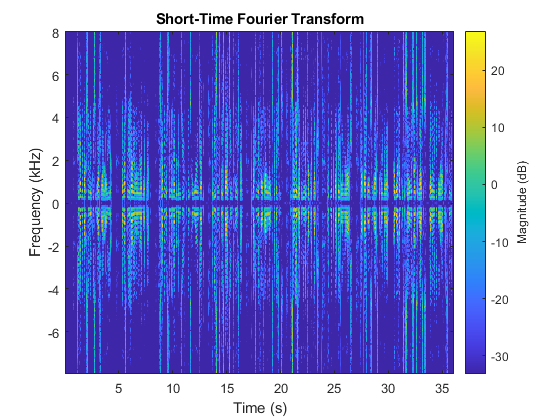

stft(s,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

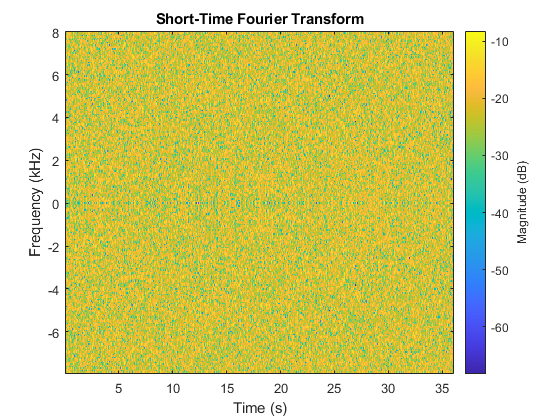

[S,SF,ST] = stft(s,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

stft(n,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

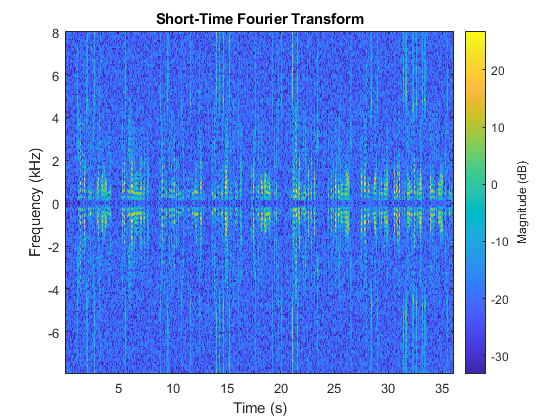

[N,NF,NT] = stft(n,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

stft(y,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

[Y,YF,YT] = stft(y,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

meanN = mean(abs(N), 2);
absYSqr = abs(Y) .^ 2;

% Option A: Regular PSD Subtraction.
% G = max(0, sqrt((absYSqr - (meanN .^ 2)) ./ absYSqr));
G = sqrt(max(0.1, 1 - (meanN .^ 2) ./ absYSqr));

% Option B: Bartlet Estimate of PSD Subtraction.
BartletL = 3;
convMat = ones(1, BartletL) / BartletL;
BartletYSqr = conv2(absYSqr, convMat, 'same');
%G = sqrt(max(0.1, (BartletYSqr - (meanN .^ 2)) ./ absYSqr));
G = sqrt(max(0.1, 1 - (meanN .^ 2) ./ BartletYSqr));

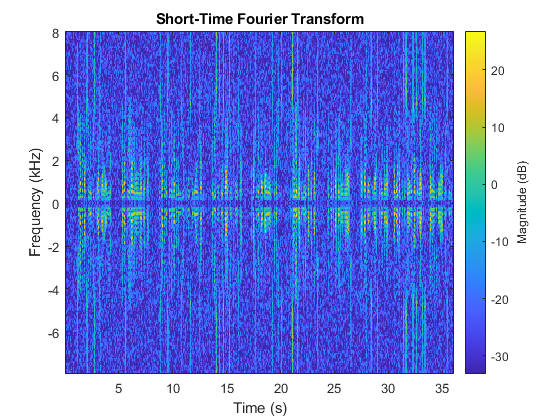

Ynr = G .* Y;
iy = istft(Ynr,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);
stft(iy,fs,'Window',hamming(256,'periodic'),'OverlapLength',128);

sound(0.1 * y, fs);

sound(0.1 * real(iy), fs);

[ix,ti] = istft(S,fs,'Window',hamming(256,'periodic'),'OverlapLength',15);

plot(t,x(:,1)','LineWidth',1.5)
hold on
plot(ti,ix(:,1)','r--')
hold off
legend('Original Channel 1','Reconstructed Channel 1')

sound(0.5 * x, fs);

sound(0.5 * ix, fs);